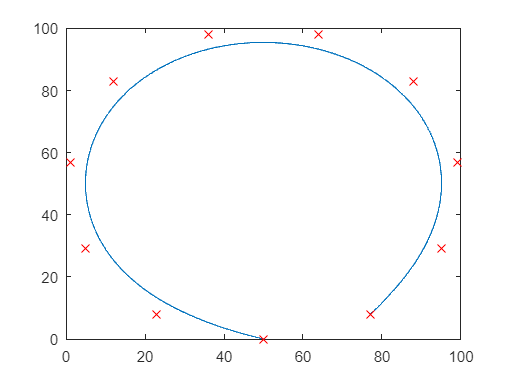

%INTEGRATOR ERROR FOR ALL 4 INTEGRALS COMPARED WITH ORIGINAL DERIVATIVES
%AND POSITION

%Position
%Control Points
order = 7;
targets = [50,0; 23,8; 5,29; 1,57; 12,83; 36,98; 64,98; 88,83; 99,57; 95,29; 77,8];
CP = points(targets, order);
CPx = CP(:,1);
CPy = CP(:,2);
%Curve Parameters
pmin = 0;
pmax = 100;
pstep = 0.1;
%Knot Vector
knot = knotvect(CP, order, pmin, pmax, pstep);
ksz = size(knot);
validpmin = knot(1, order);
validpmax = knot(1, (ksz(1,2)-order+1));
NK2MAT = [];
NK3MAT = [];
NK4MAT = [];
NK5MAT = [];
NK6MAT = [];
NK7MAT = [];
pM1 = [];
pM2 = [];
pM3 = [];
pM4 = [];
pM5 = [];
pM6 = [];
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
order = 6;
VCP = DCP(CP, knot, order);
vknot = Dkn(knot);
VelMAT = evaluate(VCP, pmin, pstep, pmax, validpmin, validpmax, vknot, order);
order = 5;
ACP = DCP(VCP, vknot, order);
aknot = Dkn(vknot);
AccMAT = evaluate(ACP, pmin, pstep, pmax, validpmin, validpmax, aknot, order);
order = 4;
JCP = DCP(ACP, aknot, order);
jknot = Dkn(aknot);
JerkMAT = evaluate(JCP, pmin, pstep, pmax, validpmin, validpmax, jknot, order);
order = 3;
SCP = DCP(JCP, jknot, order);
sknot = Dkn(jknot);
SnapMAT = evaluate(SCP, pmin, pstep, pmax, validpmin, validpmax, sknot, order);
%%%%%%%%%
%Take magnitudes
PMagMAT = absBS(PosMAT);
VMagMAT = absBS(VelMAT);
AMagMAT = absBS(AccMAT);
JMagMAT = absBS(JerkMAT);
SMagMAT = absBS(SnapMAT);
%integrate for Jerk
ijknot = Ikn(sknot, pstep);
CJ = [JCP(1,1), JCP(1,2)];
iJCP = ICP(SCP, ijknot, order, CJ);
order = order + 1;
iJMAT = evaluate(iJCP, pmin, pstep, pmax, validpmin, validpmax, ijknot, order);
iJMagMAT = absBS(iJMAT);
%integrate for Acc
iaknot = Ikn(ijknot, pstep);
CA = [ACP(1,1), ACP(1,2)];
iACP = ICP(iJCP, iaknot, order, CA);
order = order + 1;
iAMAT = evaluate(iACP, pmin, pstep, pmax, validpmin, validpmax, iaknot, order);
iAMagMAT = absBS(iAMAT);
%integrate for Vel
ivknot = Ikn(iaknot, pstep);
CV = [VCP(1,1), VCP(1,2)];
iVCP = ICP(iACP, ivknot, order, CV);
order = order + 1;
iVMAT = evaluate(iVCP, pmin, pstep, pmax, validpmin, validpmax, ivknot, order);
iVMagMAT = absBS(iVMAT);
%integrate for Pos
iknot = Ikn(ivknot, pstep);
C = [CP(1,1), CP(1,2)];
iCP = ICP(iVCP, iknot, order, C);
order = order + 1;
iPMAT = evaluate(iCP, pmin, pstep, pmax, validpmin, validpmax, iknot, order);
iPMagMAT = absBS(iPMAT);
%Display Path
plot(PosMAT(:,1),PosMAT(:,2))
hold on
scatter(CPx, CPy, 60, 'red', 'X')
hold off

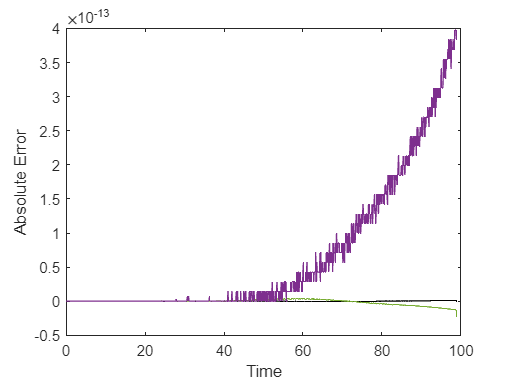

%Display Integral errors

Arel = [];
Vrel = [];
Prel = [];
%for i = 1:1:length(PMagMAT)
%    Arel = [Arel; 100*(AMagMAT(i,2)-iAMagMAT(i,2))/AMagMAT(i,2)];
%    Vrel = [Vrel; 100*(VMagMAT(i,2)-iVMagMAT(i,2))/VMagMAT(i,2)];
%    Prel = [Prel; 100*(PMagMAT(i,2)-iPMagMAT(i,2))/PMagMAT(i,2)];
%end

%plot(iJMagMAT(:,1)/100, JMagMAT(:,2)-iJMagMAT(:,2), 'red' )
%hold on
plot(iAMagMAT(:,1)/10, AMagMAT(:,2)-iAMagMAT(:,2), 'Color', "black")
hold on
plot(iVMagMAT(:,1)/10, VMagMAT(:,2)-iVMagMAT(:,2), 'Color', "#77AC30")
plot(iPMagMAT(:,1)/10, PMagMAT(:,2)-iPMagMAT(:,2), 'Color', "#7E2F8E")
xlabel('Time')
ylabel('Absolute Error')
hold off

function IP = ICP(CP, knot, k, c)
    CPx = CP(:,1);
    CPy = CP(:,2);
    n = length(CP);
    IP1 = c;
    IP = IP1;
    for i = 1:1:n
        xhold = CPx(i);
        yhold = CPy(i);
        IP2x = xhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,1);
        IP2y = yhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,2);
        IP = [IP; IP2x, IP2y];
        IP1 = [IP2x, IP2y];
    end
end
function Iknot = Ikn(knot, pstep)
    n = length(knot);
    Iknot = knot(1)-pstep;
    for i = 1:1:n
        Iknot = [Iknot, knot(i)];
    end
    Iknot = [Iknot, knot(n)+pstep];
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function pMAT = pMAT(p,knot,k)
    N = length(knot);
    pMAT = [];
    for i = 1:1:N-k
        pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
        pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
        Head = zeros(i-1,1);
        Foot = zeros(N-k-i,1);
        pvect = [Head; pconst1; pconst2; Foot];
        pMAT = [pMAT, pvect];
    end
end
function CP = points(targets, order)
    P = height(targets);
    rep = order - 1;
    CP = [];
    hold = [targets(1,1), targets(1,2)];
    for n = 1:1:rep
        CP = [CP; hold];
    end
    for i = 2:1:P-1
        hold = [targets(i,1), targets(i,2)];
        CP = [CP; hold];
    end
    hold = [targets(P,1), targets(P,2)];
    for k = 1:1:rep
        CP = [CP; hold];
    end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
    sz = size(CP);
    P = sz(1,1);
    K = P + order;
    Knot = pmin;
    for i = 1:1:order-1
        Knot = [Knot, pmin+i*pstep];
    end
    for i = 1:1:K-2*order
        Knot = [Knot, i*pmax/(K-2*order+1)];
    end
    for i = 1:1:order
        Knot = [Knot, pmax-(order-i)*pstep];
    end
end
function NK1MAT = NK1MAT(p, knot)
    N = length(knot);
    NK1MAT = [];
    for i = 1:1:N-1
        lowkn = knot(i);
        highkn = knot(i+1);
        if lowkn<=p && p<highkn
            NK1MAT = [NK1MAT, 1];
        else
            NK1MAT = [NK1MAT, 0];
        end
    end
end

function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
    BSplineMAT = [];
    for p = pmin:pstep:pmax
        if p >= validpmin
            if p<=validpmax
                k = 2;
                NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                k = 3;
                NK3MAT = NK2MAT*pMAT(p, knot, k);
                k = 4;
                if order < k
                    Pos = NK3MAT*CP;
                else
                    NK4MAT = NK3MAT*pMAT(p, knot, k);
                    k = 5;
                    if order < k
                        Pos = NK4MAT*CP;
                    else
                        NK5MAT = NK4MAT*pMAT(p, knot, k);
                        k = 6;
                        if order < k
                            Pos = NK5MAT*CP;
                        else
                            NK6MAT = NK5MAT*pMAT(p, knot, k);
                            k = 7;
                            if order < k
                                Pos = NK6MAT*CP;
                            else
                                NK7MAT = NK6MAT*pMAT(p, knot, k);
                                Pos = NK7MAT*CP;
                            end
                        end
                    end
                end
                BSplineMAT = [BSplineMAT; Pos];
            end
        end
    end
end

function DP = DCP(CP, knot, k)
    n = length(CP);
    DP = [];
    for i = 1:1:n-1
        I = i+1;
        P1 = [CP(i,1),CP(i,2)];
        P2 = [CP(i+1,1),CP(i+1,2)];
        DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
        DP = [DP; DPnew];
    end
end
function DKnot = Dkn(knot)
    N = length(knot);
    DKnot = [];
    for i = 1:1:N-2
        DKnew = knot(i+1);
        DKnot = [DKnot, DKnew];
    end
end
function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end